# ThermalSine

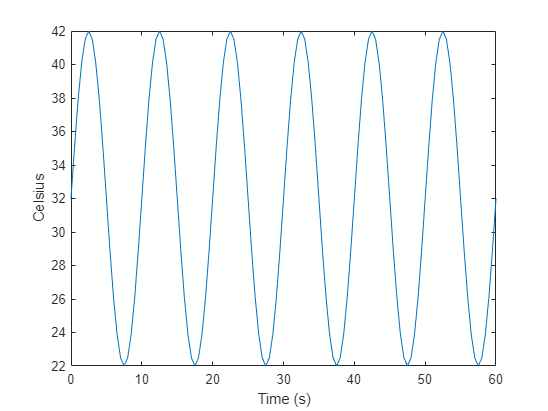

baseline = 32; % in celsius
tRange = 10; % in celsius
sineTime = 60; 
sineWidth = 10;
increment = 0.5; % in s
x = 0:increment:sineTime;
nStep = numel(x);
y = sin(x/sineWidth*2*pi)* tRange + baseline;
plot(x, y);
xlabel('Time (s)')
ylabel('Celsius')

% Define the data for each column

instruction = [{'TABLE_INFO';'STATUS';'SIN_RAMP_TO';'WAIT';'REPEAT_MARK'};
    cellstr(repmat('LIN_RAMP_TIME',nStep,1)); 
    {'REPEAT_MARK';'TABLE_INFO';'EOF'}];
Field1 = [{'START'; 'ENABLE';'FROM_ACT';'TIME';'START'};
    repmat({increment*1000},nStep,1);
    {'END';'END';' '}];

Unrecognized function or variable 'increment'.

Field2 = [{'0'; ' '; 32; 20000; ''}; 
    num2cell(y');
    {''; ''; ''}];

% Create the table
T = table(instruction, Field1, Field2,...
    'VariableNames', {'instruction', 'Field1', 'Field2'});
tableName = strcat("sineWidth_", num2str(sineWidth),"_time_",num2str(sineTime),"_range_",num2str(tRange),".csv");
writetable(T, strcat("Z:\GintyLab\Qi\stimulation\thermal\LookUpTable\Sine\",tableName));
